load short_modem_rx.mat
clf;
%msg_length = 18;

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

% recorder = audiorecorder(8192, 8, 1);
% record(recorder, 5);
% pause(6);
% y_r = getaudiodata(recorder);


start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission

fyt = linspace(0, length(y_t)/Fs, length(y_t));
plot(fyt, y_t);
xlabel("Time (s)");
ylabel("Amplitude");
title("Received Signal in Time Domain");

figure;
fyr = linspace(-Fs/2*2*pi, 2*pi*Fs/2 - 2*pi*Fs/length(y_t), length(y_t));
plot(fyr, fftshift(abs(fft(y_t))));
title("Received Signal in Frequency Domain")
xlabel("Frequency")
ylabel("Amplitude")


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
%%
%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
y_c = y_t.*c;

figure;
fyct = linspace(0, length(y_c)/Fs, length(y_c));
plot(fyct, y_c);
xlabel("Time (s)");
ylabel("Amplitude");
title("Processed Signal in Time Domain");

figure;
fycw = linspace(-Fs/2*2*pi, 2*pi*Fs/2 - 2*pi*Fs/length(y_c), length(y_c));
plot(fycw, fftshift(abs(fft(y_c))));
title("Processed Signal in Frequency Domain");
xlabel("Frequency")
ylabel("Amplitude")


%plot(y_c);

% LPF

x_d = conv(y_c, (f_c/Fs)*sinc((f_c/Fs)*[-1000:1000]'))/2;



figure;
fxdw = linspace(-Fs/2*2*pi, 2*pi*Fs/2 - 2*pi*Fs/length(x_d), length(x_d));
plot(fxdw, fftshift(abs(fft(x_d))));
title("Filtered Signal in Frequency Domain");
xlabel("Frequency");
ylabel("Amplitude");

if length(x_d) >1000 
    x_d = downsample(x_d, 100);
end

figure;
fxdt = linspace(0, length(x_d)/Fs*100, length(x_d));
plot(fxdt, x_d);
xlabel("Time (s)");
ylabel("Amplitude");
title("Filtered and Downsampled Signal in Time Domain");


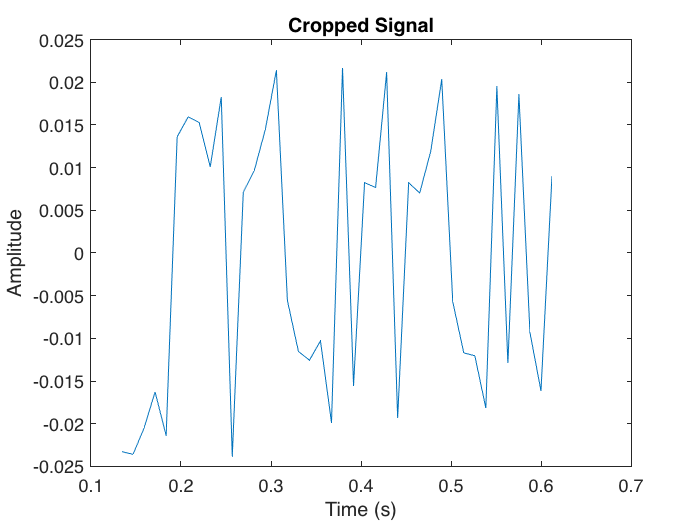

x_d_cut = x_d(12:12+msg_length*8 -1);
plot(fxdt(12:12 + msg_length*8 -1), x_d_cut);
xlabel("Time (s)");
ylabel("Amplitude");
title("Cropped Signal")

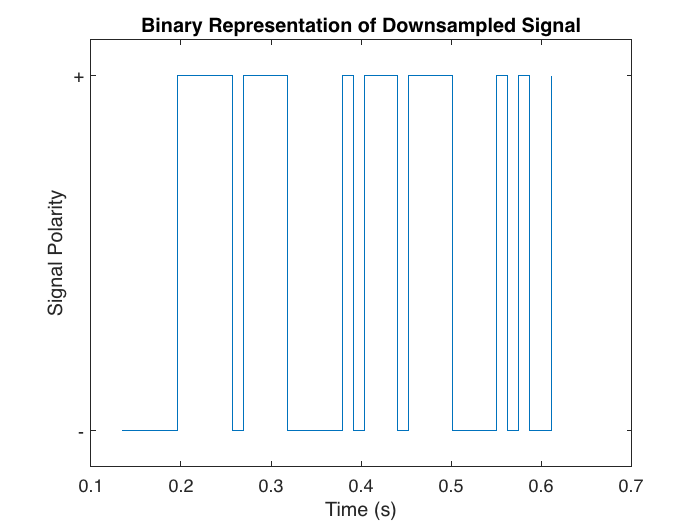


xdbinx = linspace(fxdt(12), fxdt(12+msg_length*8 -1), length(x_d_cut));
stairs(xdbinx, x_d_cut>0)
ylim([-0.1 1.1]);
yticks([0 1]);
yticklabels(["-", "+"])
xlabel("Time (s)");
ylabel("Signal Polarity")
title("Binary Representation of Downsampled Signal")


bits = x_d_cut>0;

% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits

BitsToString(bits)

